clc; clear;
load('monitoring_data.mat')
close all;

plots_dir = fullfile(pwd, 'plots');
if ~exist(plots_dir, 'dir'), mkdir(plots_dir); end



## 1. Setup & Initialization

### Initialization

#### training data $Z_{train}$ (**N = 10000** stationary healthy samples):

#### 
$$R_0 = \text{corr}(Z_{\text{train}}) \in \mathbb{R}^{m \times m}, \qquad \hat{b}_0 = \mu_{\text{train}} \in \mathbb{R}^m$$


#### $R_{0,ii}=1$ for all **i** by construction. From k= onward both $R_k$  and $\hat{b}_k$ � are updated recursively at each incoming sample.

**Forgetting Factor**

Three values are tested:

#### where $W_{\text{eff}} = \frac{1}{1-\lambda}$ is the effective memory window.

#### **Lanczos Parameters**

**Monitoring Datasets**

%% 1. Setup

% Lanczos parameters
rho       = 0.995;    % variance threshold for Lanczos stopping
q_max     = 5;        % max PCs to extract
eps_bis   = 1e-10;    % bisection precision
delta_inv = 1e-10;    % inverse iteration perturbation

% RPCA parameters
lambdas = [0.98, 0.995, 0.999];
W_eff   = round(1 ./ (1 - lambdas));   % effective window sizes [50, 200, 1000]
B=10;   % block size for block-wise 

% Batch PCA initialization (SVD on training data)
[~, S, V] = svd(Z, 'econ');
q          = 3;
Vq         = V(:, 1:q);
sv         = diag(S);
eigenvalues = sv.^2 / (N-1);

% Training thresholds (Batch PCA)
scores_train = Z * Vq;
SPE_train    = sum((Z - scores_train*Vq').^2, 2);
T2_train     = sum((scores_train ./ eigenvalues(1:q)') .* scores_train, 2);
SPE_lim_batch = quantile(SPE_train, 0.95);
T2_lim_batch  = (q*(N-1)*(N+1)) / (N*(N-q)) * finv(0.95, q, N-q);

% Datasets to process
datasets     = {Z_mon_drift, Z_mon_f1, Z_mon_f2, Z_mon_f3, Z_mon};
dataset_names = {'Drift only', 'Fault 1: Spike x_5', ...
                 'Fault 2: Incipient x_4', 'Fault 3: Step x_1', 'Full dataset'};

fprintf('q=%d | lambdas=[%.3f %.3f %.3f] | B=%d\n', ...
        q, lambdas(1), lambdas(2), lambdas(3), B)

q=3 | lambdas=[0.980 0.995 0.999] | B=10


## 2. Sample-wise RPCA: Lanczos + VRE (3 λ, all datasets)

### Loops over all 5 monitoring datasets and all 3 values of λ:

####     At each sample k: updates $\hat{b}_k$ and $R_k
$ recursively via forgetting factor

- **    Calls **`lanczos_tridiag.m`** → reduces **$R_k$** to tridiagonal **$\Gamma \in \mathbb{R}^{m_1 \times m_1}$

- **    Calls **`bisection_eig.m`** + **`sturm_count.m`** → extracts top **$q_{\max}$**  eigenvalues of Γ**

- **    Calls **`inverse_iteration.m`** → recovers eigenvectors → builds loading matrix **$P_k$

- **    Computes VRE for **$q=1$**, **$\ldots, q_{\max}$** → selects optimal **$q_k^*$ 

- **    Computes **$\text{SPE}_k$** and **$T^2_k$** with adaptive thresholds**

- **    Results stored in **`SPE_sw`**, **`T2_sw`**, **`SPElim_sw`**, **`T2lim_sw`**, **`q_sw`** . cell arrays of size (dataset, λ)**

### Step 1 — Recursive Mean Update (Eq. 15)

####         
$$\hat{b}_k = \lambda \hat{b}_{k-1} + (1-\lambda) x_k$$


####         
$$\Delta\hat{b}_k = \hat{b}_k - \hat{b}_{k-1}$$


#### Step 2 — Recursive Correlation Matrix Update (Eq. 20)

####         
$$R_k = \lambda R_{k-1} + v_1 v_1^\top + v_2 v_2^\top$$


####         
$$v_1 = \frac{\Delta\hat{b}_k}{\sigma_1}, \qquad v_2 = \sqrt{1-\lambda}\,\tilde{x}_k, \qquad \tilde{x}_k = \frac{x_k - \hat{b}_k}{\sigma_1}$$


#### Step 3 — Lanczos Tridiagonalization

####         
$$R_k \Phi = \Phi \Gamma, \qquad \Phi^\top \Phi = I_{m_1}

$$


#### Step 4 — Eigenvalues via Bisection + Sturm (Eq. 32)

####         
$$s(\mu) = \#\{\lambda_i(\Gamma) < \mu\}$$


####         
$$\lambda_i^* = \text{bisect}\left(s(\mu) = m_1 - i,\; \varepsilon = 10^{-10}\right)$$


#### Step 5 — Eigenvectors via Inverse Iteration

####         
$$\left(\Gamma - \lambda_i I + \delta I\right) c_i^{(\text{new})} = c_i^{(\text{old})}

$$


####         
$$P_k = \Phi\, C, \qquad C = \left[c_1 \mid \cdots \mid c_{q_k}\right] \in \mathbb{R}^{m_1 \times q_k}$$


#### Step 6 — VRE: Optimal $q_k$ Selection (Eq. 37–38)

####         
$$u_i(q) = \frac{R_{k,ii} - 2\,c_i^\top r_i + c_i^\top R_k\, c_i}{(1 - c_{ii})^2}


$$


####         
$$\text{VRE}(q) = \sum_{i=1}^{m} \frac{u_i(q)}{R_{k,ii}}$$


#### Step 7 — SPE and $T^2 $ with Adaptive Thresholds

####         
$$\text{SPE}_k = \|\tilde{x}_k - P_k P_k^\top \tilde{x}_k\|^2$$


####         
$$T^2_k = z_k^\top \Lambda_{q_k}^{-1} z_k, \qquad z_k = P_k^\top \tilde{x}_k


$$


####         
$$T^2_{\text{lim},k} = \chi^2_{0.95}(q_k^*)$$


####         
$$\text{SPE}_{\text{lim},k} = \theta_1 \left(\frac{\sqrt{2\theta_2 h_0^2}}{\theta_1}\, z_{0.95} + 1 + \frac{\theta_2 h_0(h_0-1)}{\theta_1^2}\right)^{1/h_0}$$


#### where:

####         
$$\theta_j = \sum_{i=q_k^*+1}^{m_1} \lambda_i^j, \quad j=1,2,3 \qquad h_0 = 1 - \frac{2\theta_1\theta_3}{3\theta_2^2}$$


%% 2. Sample-wise RPCA: Lanczos + VRE (3 λ, all datasets)

n_ds  = length(datasets);
n_lam = length(lambdas);

% Storage: cell(dataset, lambda) → vector(N_cur)
SPE_sw    = cell(n_ds, n_lam);
T2_sw     = cell(n_ds, n_lam);
SPElim_sw = cell(n_ds, n_lam);
T2lim_sw  = cell(n_ds, n_lam);
q_sw      = cell(n_ds, n_lam);

for di = 1:n_ds

    Z_cur = datasets{di};
    X_cur = Z_cur .* sigma + mu;   % denormalize for mu update
    N_cur = size(Z_cur, 1);

    for li = 1:n_lam

        lam = lambdas(li);

        % --- Initialization ---
        mu_r = mu';         % recursive mean
        R_r  = cov(Z);      % recursive correlation matrix (from training)

        SPE_vec    = zeros(N_cur, 1);
        T2_vec     = zeros(N_cur, 1);
        SPElim_vec = zeros(N_cur, 1);
        T2lim_vec  = zeros(N_cur, 1);
        q_vec      = zeros(N_cur, 1);

        for k = 1:N_cur

            x_raw = X_cur(k,:)';

            %% Step 1: Recursive update of mean and R (Eq. 20)
            mu_old  = mu_r;
            mu_r    = lam * mu_r + (1-lam) * x_raw;
            delta_b = mu_r - mu_old;
            x_tilde = (x_raw - mu_r) ./ sigma';   % normalized sample

            v1  = delta_b ./ sigma';               % mean shift term
            v2  = sqrt(1-lam) * x_tilde;           % new sample term
            R_r = lam * R_r + v1*v1' + v2*v2';    % rank-2 update

            %% Step 2: Lanczos tridiagonalization of R_k
            [Phi, alpha_l, beta_l, m1] = lanczos_tridiag(R_r, rho, q_max);
            n_eig = min(m1, q_max);

            %% Step 3: Eigenvalues via bisection + Sturm sequence
            lambda_eig = zeros(n_eig, 1);
            for i = 1:n_eig
                lambda_eig(i) = bisection_eig(alpha_l, beta_l, i, eps_bis);
            end

            %% Step 4: Eigenvectors via inverse iteration
            C_lk = zeros(m1, n_eig);
            for i = 1:n_eig
                C_lk(:,i) = inverse_iteration(alpha_l, beta_l, lambda_eig(i), delta_inv);
            end
            P_full = Phi * C_lk;   % full loading matrix (m x n_eig)

            %% Step 5: VRE: select optimal q_k (Eq. 37-38)
            VRE_test = zeros(n_eig, 1);
            for q_test = 1:n_eig
                P_t    = P_full(:, 1:q_test);
                C_t    = P_t * P_t';
                u_var  = zeros(m, 1);
                for j = 1:m
                    num      = R_r(j,j) - 2*C_t(:,j)'*R_r(:,j) + C_t(:,j)'*R_r*C_t(:,j);
                    den      = (1 - C_t(j,j))^2;
                    u_var(j) = max(num/den, 1e-10);
                end
                VRE_test(q_test) = sum(u_var ./ diag(R_r));
            end
            [~, q_opt] = min(VRE_test);
            q_vec(k)   = q_opt;

            %% Step 6: SPE and T² with adaptive thresholds
            P_lk       = P_full(:, 1:q_opt);
            scores_k   = P_lk' * x_tilde;
            residual_k = x_tilde - P_lk * scores_k;

            SPE_vec(k) = residual_k' * residual_k;
            T2_vec(k)  = scores_k' * diag(1./lambda_eig(1:q_opt)) * scores_k;

            % SPE limit: Jackson-Mudholkar (Eq. 40)
            if m1 > q_opt
                lambda_res = zeros(m1-q_opt, 1);
                for i = 1:m1-q_opt
                    lambda_res(i) = bisection_eig(alpha_l, beta_l, q_opt+i, eps_bis);
                end
                lambda_res = max(lambda_res, 1e-10);
                theta1 = sum(lambda_res);
                theta2 = sum(lambda_res.^2);
                theta3 = sum(lambda_res.^3);
                h0     = max(1 - (2*theta1*theta3)/(3*theta2^2), 1e-6);
                SPElim_vec(k) = theta1 * (sqrt(2*theta2*h0^2)/theta1 * norminv(0.95) + ...
                                1 + theta2*h0*(h0-1)/theta1^2)^(1/h0);
            else
                SPElim_vec(k) = SPElim_vec(max(k-1, 1));
            end

            % T² limit: chi-squared (Section 7.1)
            T2lim_vec(k) = chi2inv(0.95, q_opt);

        end

        % Store results
        SPE_sw{di,li}    = SPE_vec;
        T2_sw{di,li}     = T2_vec;
        SPElim_sw{di,li} = SPElim_vec;
        T2lim_sw{di,li}  = T2lim_vec;
        q_sw{di,li}      = q_vec;

    end

    fprintf('Dataset %d/%d: %s\n', di, n_ds, dataset_names{di})
end

Dataset 1/5: Drift only
Dataset 2/5: Fault 1: Spike x_5
Dataset 3/5: Fault 2: Incipient x_4
Dataset 4/5: Fault 3: Step x_1
Dataset 5/5: Full dataset


## 3. Sample-wise RPCA: Results (λ comparison, all datasets)

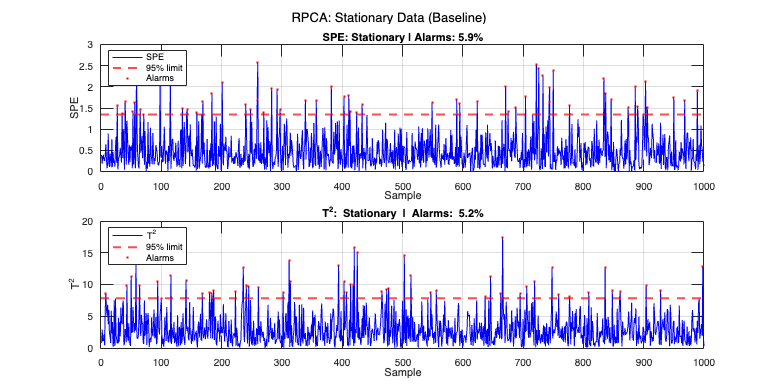

%% 3. Sample-wise RPCA: Results (λ comparison, all datasets)

colors_lam = {[0.15 0.45 0.80], [0.85 0.45 0.00], [0.40 0.70 0.20]};
lam_labels = {'λ=0.980 (W=50)', 'λ=0.995 (W=200)', 'λ=0.999 (W=1000)'};

%% 3a: Stationary Baseline

Z_stat   = Z(1:1000,:);
sc_stat  = Z_stat * Vq;
SPE_stat = sum((Z_stat - sc_stat*Vq').^2, 2);
T2_stat  = sum((sc_stat ./ eigenvalues(1:q)') .* sc_stat, 2);

figure('Position', [100 100 1000 500])

subplot(2,1,1); hold on
plot(SPE_stat, 'b-', 'LineWidth', 0.9)
yline(SPE_lim_batch, 'r--', 'LineWidth', 2)
alarm_idx = find(SPE_stat > SPE_lim_batch);
plot(alarm_idx, SPE_stat(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('SPE')
title(sprintf('SPE: Stationary | Alarms: %.1f%%', 100*mean(SPE_stat > SPE_lim_batch)))
legend('SPE','95% limit','Alarms','Location','northwest')
grid on; box on

subplot(2,1,2); hold on
plot(T2_stat, 'b-', 'LineWidth', 0.9)
yline(T2_lim_batch, 'r--', 'LineWidth', 2)
alarm_idx = find(T2_stat > T2_lim_batch);
plot(alarm_idx, T2_stat(alarm_idx), 'r.', 'MarkerSize', 6)
xlabel('Sample'); ylabel('T^2')
title(sprintf('T^2: Stationary | Alarms: %.1f%%', 100*mean(T2_stat > T2_lim_batch)))
legend('T^2','95% limit','Alarms','Location','northwest')
grid on; box on

sgtitle('RPCA: Stationary Data (Baseline)', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_3a_stationary.png'), 'Resolution', 300)

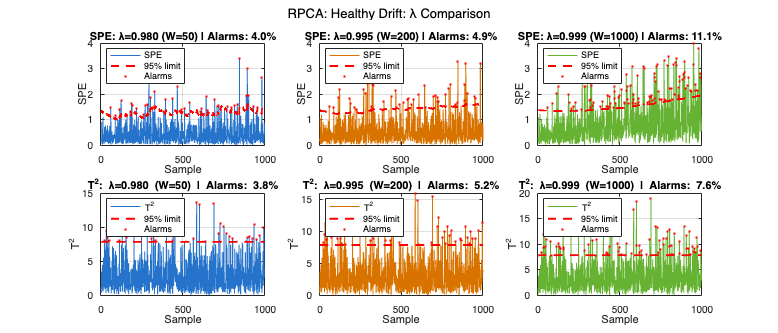


%% 3b: Drift Only (λ comparison)

di = 1;

figure('Position', [100 100 1400 600])

for li = 1:3
    SPE_cur    = SPE_sw{di, li};
    T2_cur     = T2_sw{di, li};
    SPElim_cur = SPElim_sw{di, li};
    T2lim_cur  = T2lim_sw{di, li};

    subplot(2,3,li); hold on
    plot(SPE_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(SPElim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(SPE_cur > SPElim_cur);
    plot(alarm_idx, SPE_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE')
    title(sprintf('SPE: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(SPE_cur > SPElim_cur)))
    legend('SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    subplot(2,3,li+3); hold on
    plot(T2_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(T2lim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(T2_cur > T2lim_cur);
    plot(alarm_idx, T2_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2')
    title(sprintf('T^2: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(T2_cur > T2lim_cur)))
    legend('T^2','95% limit','Alarms','Location','northwest')
    grid on; box on
end

sgtitle('RPCA: Healthy Drift: λ Comparison', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_3b_drift.png'), 'Resolution', 300)

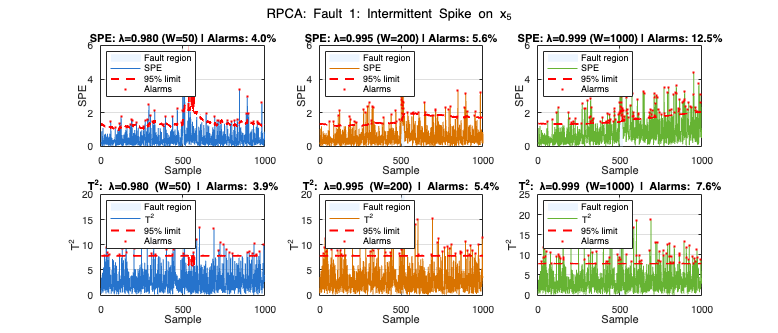


%% 3c: Fault 1: Spike on x5 (λ comparison)

di = 2;

figure('Position', [100 100 1400 600])

for li = 1:3
    SPE_cur    = SPE_sw{di, li};
    T2_cur     = T2_sw{di, li};
    SPElim_cur = SPElim_sw{di, li};
    T2lim_cur  = T2lim_sw{di, li};

    subplot(2,3,li); hold on
    fill([500 520 520 500], [0 0 max(SPE_cur)*1.2 max(SPE_cur)*1.2], ...
         fault_colors(1,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(SPE_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(SPElim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(SPE_cur > SPElim_cur);
    plot(alarm_idx, SPE_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE')
    title(sprintf('SPE: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(SPE_cur > SPElim_cur)))
    legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    subplot(2,3,li+3); hold on
    fill([500 520 520 500], [0 0 max(T2_cur)*1.2 max(T2_cur)*1.2], ...
         fault_colors(1,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(T2_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(T2lim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(T2_cur > T2lim_cur);
    plot(alarm_idx, T2_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2')
    title(sprintf('T^2: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(T2_cur > T2lim_cur)))
    legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
    grid on; box on
end

sgtitle('RPCA: Fault 1: Intermittent Spike on x_5', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_3c_fault1.png'), 'Resolution', 300)

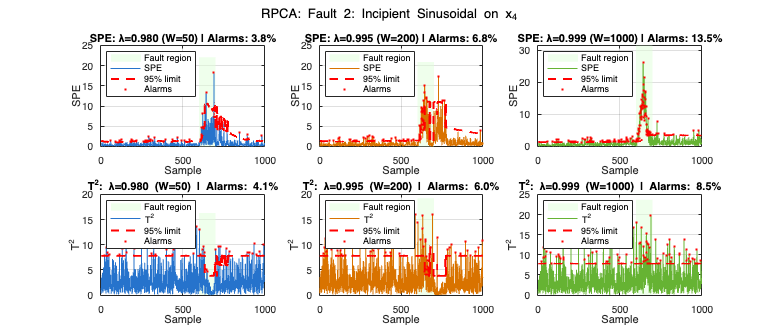


%% 3d: Fault 2: Incipient sinusoidal on x4 (λ comparison)

di = 3;

figure('Position', [100 100 1400 600])

for li = 1:3
    SPE_cur    = SPE_sw{di, li};
    T2_cur     = T2_sw{di, li};
    SPElim_cur = SPElim_sw{di, li};
    T2lim_cur  = T2lim_sw{di, li};

    subplot(2,3,li); hold on
    fill([600 700 700 600], [0 0 max(SPE_cur)*1.2 max(SPE_cur)*1.2], ...
         fault_colors(2,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(SPE_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(SPElim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(SPE_cur > SPElim_cur);
    plot(alarm_idx, SPE_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE')
    title(sprintf('SPE: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(SPE_cur > SPElim_cur)))
    legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    subplot(2,3,li+3); hold on
    fill([600 700 700 600], [0 0 max(T2_cur)*1.2 max(T2_cur)*1.2], ...
         fault_colors(2,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(T2_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(T2lim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(T2_cur > T2lim_cur);
    plot(alarm_idx, T2_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2')
    title(sprintf('T^2: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(T2_cur > T2lim_cur)))
    legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
    grid on; box on
end

sgtitle('RPCA: Fault 2: Incipient Sinusoidal on x_4', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_3d_fault2.png'), 'Resolution', 300)

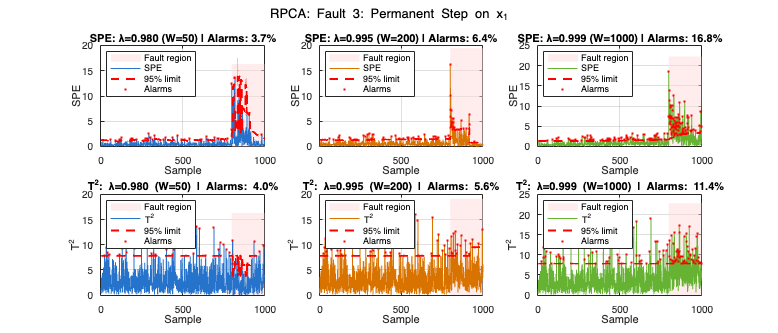


%% 3e: Fault 3: Permanent step on x1 (λ comparison)

di = 4;

figure('Position', [100 100 1400 600])

for li = 1:3
    SPE_cur    = SPE_sw{di, li};
    T2_cur     = T2_sw{di, li};
    SPElim_cur = SPElim_sw{di, li};
    T2lim_cur  = T2lim_sw{di, li};

    subplot(2,3,li); hold on
    fill([800 1000 1000 800], [0 0 max(SPE_cur)*1.2 max(SPE_cur)*1.2], ...
         fault_colors(3,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(SPE_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(SPElim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(SPE_cur > SPElim_cur);
    plot(alarm_idx, SPE_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE')
    title(sprintf('SPE: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(SPE_cur > SPElim_cur)))
    legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    subplot(2,3,li+3); hold on
    fill([800 1000 1000 800], [0 0 max(T2_cur)*1.2 max(T2_cur)*1.2], ...
         fault_colors(3,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(T2_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(T2lim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(T2_cur > T2lim_cur);
    plot(alarm_idx, T2_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2')
    title(sprintf('T^2: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(T2_cur > T2lim_cur)))
    legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
    grid on; box on
end

sgtitle('RPCA: Fault 3: Permanent Step on x_1', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_3e_fault3.png'), 'Resolution', 300)

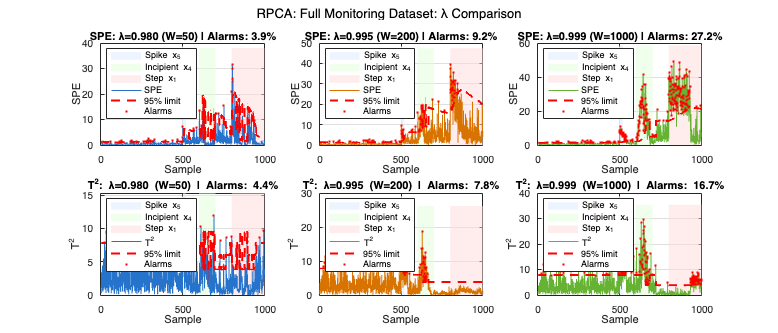


%% 3f: Full Monitoring Dataset (λ comparison)

di = 5;

figure('Position', [100 100 1400 600])

for li = 1:3
    SPE_cur    = SPE_sw{di, li};
    T2_cur     = T2_sw{di, li};
    SPElim_cur = SPElim_sw{di, li};
    T2lim_cur  = T2lim_sw{di, li};

    subplot(2,3,li); hold on
    for f = 1:3
        fill([fault_regions(f,1) fault_regions(f,2) ...
              fault_regions(f,2) fault_regions(f,1)], ...
             [0 0 max(SPE_cur)*1.2 max(SPE_cur)*1.2], ...
             fault_colors(f,:), 'EdgeColor','none','FaceAlpha',0.5)
    end
    plot(SPE_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(SPElim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(SPE_cur > SPElim_cur);
    plot(alarm_idx, SPE_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE')
    title(sprintf('SPE: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(SPE_cur > SPElim_cur)))
    legend('Spike x_5','Incipient x_4','Step x_1', ...
           'SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    subplot(2,3,li+3); hold on
    for f = 1:3
        fill([fault_regions(f,1) fault_regions(f,2) ...
              fault_regions(f,2) fault_regions(f,1)], ...
             [0 0 max(T2_cur)*1.2 max(T2_cur)*1.2], ...
             fault_colors(f,:), 'EdgeColor','none','FaceAlpha',0.5)
    end
    plot(T2_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(T2lim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(T2_cur > T2lim_cur);
    plot(alarm_idx, T2_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2')
    title(sprintf('T^2: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(T2_cur > T2lim_cur)))
    legend('Spike x_5','Incipient x_4','Step x_1', ...
           'T^2','95% limit','Alarms','Location','northwest')
    grid on; box on
end

sgtitle('RPCA: Full Monitoring Dataset: λ Comparison', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_3f_full.png'), 'Resolution', 300)

## 4. VRE Visualization

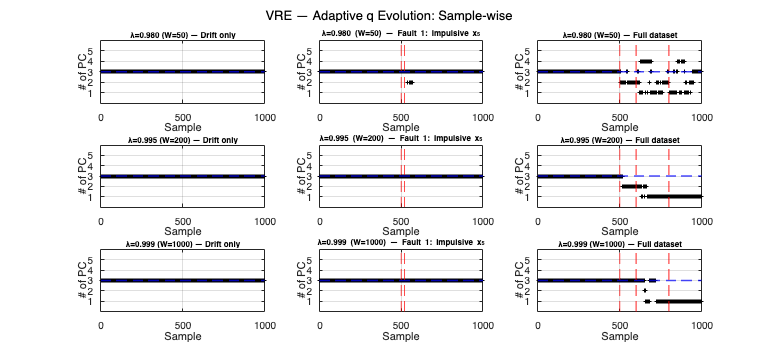

%% 4a — Adaptive q Evolution (3 λ, drift / fault1 / full)

di_list    = [1, 2, 5];
di_labels  = {'Drift only', 'Fault 1: Impulsive x_5', 'Full dataset'};

figure('Position', [100 100 1400 650])

for li = 1:3
    for di_idx = 1:3
        di = di_list(di_idx);
        subplot(3, 3, (li-1)*3 + di_idx); hold on

        plot(1:N2, q_sw{di,li}, 'k+', 'MarkerSize', 4, 'LineWidth', 0.8)
        yline(3, 'b--', 'LineWidth', 1.5)

        if di == 2
            xline(fault_regions(1,1), 'r--', 'LineWidth', 1.2)
            xline(fault_regions(1,2), 'r--', 'LineWidth', 1.2)
        elseif di == 5
            for f = 1:3
                xline(fault_regions(f,1), 'r--', 'LineWidth', 1.2)
            end
        end

        ylim([0 q_max+1])
        yticks(1:q_max)
        xlabel('Sample'); ylabel('# of PC')
        title(sprintf('%s — %s', lam_labels{li}, di_labels{di_idx}), 'FontSize', 8)
        grid on; box on
    end
end

sgtitle('VRE — Adaptive q Evolution: Sample-wise', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_4a_q_evolution.png'), 'Resolution', 300)

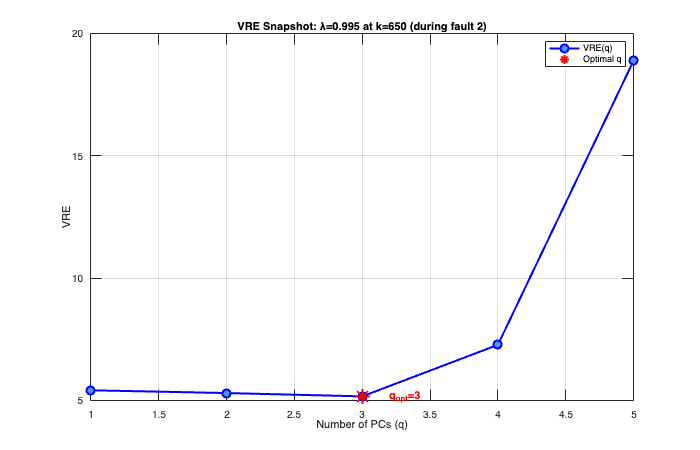


%% 4b: VRE Snapshot at k=650 (pre-fault, λ=0.995)

li  = 3;    % λ=0.995
k_snapshot = 650;

% Recompute R_k at k=250 by fast-forwarding the loop
lam  = lambdas(li);
mu_r = mu';
R_r  = cov(Z);

X_cur = Z_mon .* sigma + mu;

for k = 1:k_snapshot
    x_raw   = X_cur(k,:)';
    mu_old  = mu_r;
    mu_r    = lam * mu_r + (1-lam) * x_raw;
    delta_b = mu_r - mu_old;
    x_tilde = (x_raw - mu_r) ./ sigma';
    v1      = delta_b ./ sigma';
    v2      = sqrt(1-lam) * x_tilde;
    R_r     = lam * R_r + v1*v1' + v2*v2';
end

% Lanczos at k_snapshot
[Phi, alpha_l, beta_l, m1] = lanczos_tridiag(R_r, rho, q_max);
n_eig = min(m1, q_max);

lambda_eig = zeros(n_eig, 1);
for i = 1:n_eig
    lambda_eig(i) = bisection_eig(alpha_l, beta_l, i, eps_bis);
end

C_lk = zeros(m1, n_eig);
for i = 1:n_eig
    C_lk(:,i) = inverse_iteration(alpha_l, beta_l, lambda_eig(i), delta_inv);
end
P_full = Phi * C_lk;

% Compute VRE for q = 1:n_eig
VRE_snapshot = zeros(n_eig, 1);
for q_test = 1:n_eig
    P_t   = P_full(:, 1:q_test);
    C_t   = P_t * P_t';
    u_var = zeros(m, 1);
    for j = 1:m
        num      = R_r(j,j) - 2*C_t(:,j)'*R_r(:,j) + C_t(:,j)'*R_r*C_t(:,j);
        den      = (1 - C_t(j,j))^2;
        u_var(j) = max(num/den, 1e-10);
    end
    VRE_snapshot(q_test) = sum(u_var ./ diag(R_r));
end

[VRE_min, q_min] = min(VRE_snapshot);

figure('Position', [100 100 700 450])
plot(1:n_eig, VRE_snapshot, 'b-o', 'LineWidth', 2, 'MarkerSize', 8, ...
     'MarkerFaceColor', [0.3 0.6 0.9])
hold on
plot(q_min, VRE_min, 'r*', 'MarkerSize', 15, 'LineWidth', 2)
text(q_min+0.1, VRE_min, sprintf('  q_{opt}=%d', q_min), ...
     'FontSize', 11, 'FontWeight', 'bold', 'Color', 'r')
xlabel('Number of PCs (q)')
ylabel('VRE')
title(sprintf('VRE Snapshot: λ=0.995 at k=%d (during fault 2)', k_snapshot))
legend('VRE(q)', 'Optimal q', 'Location', 'northeast')
grid on; box on

exportgraphics(gcf, fullfile(plots_dir, 'rpca_4b_vre_snapshot.png'), 'Resolution', 300)

## 5. Block-wise RPCA Loop (3 λ, all datasets)

#### **We use B=5 (Compute RPCA every 5 samples)**

%% 5. Block-wise RPCA Loop (3 λ, all datasets)

B= 5;   % block size for block-wise

SPE_bw    = cell(n_ds, n_lam);
T2_bw     = cell(n_ds, n_lam);
SPElim_bw = cell(n_ds, n_lam);
T2lim_bw  = cell(n_ds, n_lam);
q_bw      = cell(n_ds, n_lam);

for di = 1:n_ds

    Z_cur = datasets{di};
    X_cur = Z_cur .* sigma + mu;
    N_cur = size(Z_cur, 1);

    for li = 1:n_lam

        lam = lambdas(li);

        % --- Initialization ---
        mu_r   = mu';
        R_r    = cov(Z);
        buffer = zeros(B, m);
        n_buf  = 0;

        % Initial Lanczos + VRE on R_0
        [Phi, alpha_l, beta_l, m1] = lanczos_tridiag(R_r, rho, q_max);
        n_eig = min(m1, q_max);

        lambda_eig = zeros(n_eig, 1);
        for i = 1:n_eig
            lambda_eig(i) = bisection_eig(alpha_l, beta_l, i, eps_bis);
        end
        C_lk = zeros(m1, n_eig);
        for i = 1:n_eig
            C_lk(:,i) = inverse_iteration(alpha_l, beta_l, lambda_eig(i), delta_inv);
        end
        P_full = Phi * C_lk;

        VRE_init = zeros(n_eig, 1);
        for q_test = 1:n_eig
            P_t   = P_full(:, 1:q_test);
            C_t   = P_t * P_t';
            u_var = zeros(m, 1);
            for j = 1:m
                num      = R_r(j,j) - 2*C_t(:,j)'*R_r(:,j) + C_t(:,j)'*R_r*C_t(:,j);
                den      = (1 - C_t(j,j))^2;
                u_var(j) = max(num/den, 1e-10);
            end
            VRE_init(q_test) = sum(u_var ./ diag(R_r));
        end
        [~, q_cur]  = min(VRE_init);
        P_cur       = P_full(:, 1:q_cur);
        lambda_cur  = lambda_eig(1:q_cur);

        SPE_vec    = zeros(N_cur, 1);
        T2_vec     = zeros(N_cur, 1);
        SPElim_vec = zeros(N_cur, 1);
        T2lim_vec  = zeros(N_cur, 1);
        q_vec      = zeros(N_cur, 1);

        for k = 1:N_cur

            x_raw   = X_cur(k,:)';
            x_tilde = (x_raw - mu_r) ./ sigma';

            %% Detection with current model
            scores_k   = P_cur' * x_tilde;
            residual_k = x_tilde - P_cur * scores_k;

            SPE_vec(k)   = residual_k' * residual_k;
            T2_vec(k)    = scores_k' * diag(1./lambda_cur) * scores_k;
            T2lim_vec(k) = chi2inv(0.95, q_cur);
            q_vec(k)     = q_cur;

            % SPE limit
            if m1 > q_cur
                lambda_res = zeros(m1-q_cur, 1);
                for i = 1:m1-q_cur
                    lambda_res(i) = bisection_eig(alpha_l, beta_l, q_cur+i, eps_bis);
                end
                lambda_res = max(lambda_res, 1e-10);
                theta1 = sum(lambda_res);
                theta2 = sum(lambda_res.^2);
                theta3 = sum(lambda_res.^3);
                h0     = max(1 - (2*theta1*theta3)/(3*theta2^2), 1e-6);
                SPElim_vec(k) = theta1 * (sqrt(2*theta2*h0^2)/theta1 * norminv(0.95) + ...
                                1 + theta2*h0*(h0-1)/theta1^2)^(1/h0);
            else
                SPElim_vec(k) = SPElim_vec(max(k-1, 1));
            end

            %% Buffer accumulation
            n_buf = n_buf + 1;
            buffer(n_buf,:) = x_raw';

            %% Model update every B samples
            if n_buf == B

                x_block_mean = mean(buffer, 1)';
                mu_old  = mu_r;
                mu_r    = lam * mu_r + (1-lam) * x_block_mean;
                delta_b = mu_r - mu_old;

                x_norm_block = (buffer - mu_r') ./ sigma;
                v1  = delta_b ./ sigma';
                R_r = lam * R_r + v1*v1' + (1-lam) * (x_norm_block' * x_norm_block) / B;
                R_r = (R_r + R_r') / 2;

                [Phi, alpha_l, beta_l, m1] = lanczos_tridiag(R_r, rho, q_max);
                n_eig = min(m1, q_max);

                lambda_eig = zeros(n_eig, 1);
                for i = 1:n_eig
                    lambda_eig(i) = bisection_eig(alpha_l, beta_l, i, eps_bis);
                end
                C_lk = zeros(m1, n_eig);
                for i = 1:n_eig
                    C_lk(:,i) = inverse_iteration(alpha_l, beta_l, lambda_eig(i), delta_inv);
                end
                P_full = Phi * C_lk;

                VRE_test = zeros(n_eig, 1);
                for q_test = 1:n_eig
                    P_t   = P_full(:, 1:q_test);
                    C_t   = P_t * P_t';
                    u_var = zeros(m, 1);
                    for j = 1:m
                        num      = R_r(j,j) - 2*C_t(:,j)'*R_r(:,j) + C_t(:,j)'*R_r*C_t(:,j);
                        den      = (1 - C_t(j,j))^2;
                        u_var(j) = max(num/den, 1e-10);
                    end
                    VRE_test(q_test) = sum(u_var ./ diag(R_r));
                end
                [~, q_cur]  = min(VRE_test);
                P_cur       = P_full(:, 1:q_cur);
                lambda_cur  = lambda_eig(1:q_cur);

                buffer = zeros(B, m);
                n_buf  = 0;
            end

        end

        SPE_bw{di,li}    = SPE_vec;
        T2_bw{di,li}     = T2_vec;
        SPElim_bw{di,li} = SPElim_vec;
        T2lim_bw{di,li}  = T2lim_vec;
        q_bw{di,li}      = q_vec;

    end

end

## 6. Block-wise RPCA: Results (3 λ comparison, all datasets)

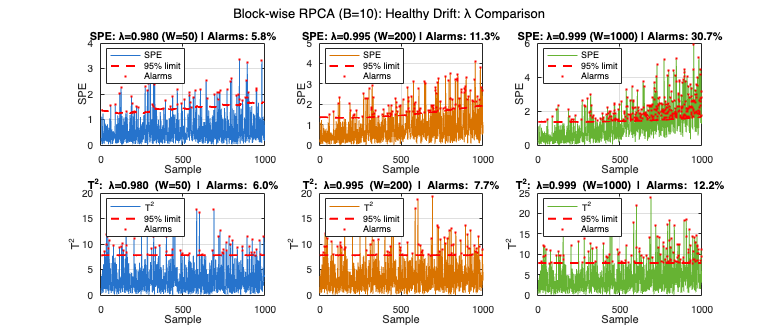


%% 6. Block-wise RPCA: Results (3 λ comparison, all datasets)

%% 6a: Drift Only

di = 1;

figure('Position', [100 100 1400 600])

for li = 1:3
    SPE_cur    = SPE_bw{di, li};
    T2_cur     = T2_bw{di, li};
    SPElim_cur = SPElim_bw{di, li};
    T2lim_cur  = T2lim_bw{di, li};

    subplot(2,3,li); hold on
    plot(SPE_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(SPElim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(SPE_cur > SPElim_cur);
    plot(alarm_idx, SPE_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE')
    title(sprintf('SPE: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(SPE_cur > SPElim_cur)))
    legend('SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    subplot(2,3,li+3); hold on
    plot(T2_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(T2lim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(T2_cur > T2lim_cur);
    plot(alarm_idx, T2_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2')
    title(sprintf('T^2: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(T2_cur > T2lim_cur)))
    legend('T^2','95% limit','Alarms','Location','northwest')
    grid on; box on
end

sgtitle('Block-wise RPCA (B=10): Healthy Drift: λ Comparison', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_6a_bw_drift.png'), 'Resolution', 300)

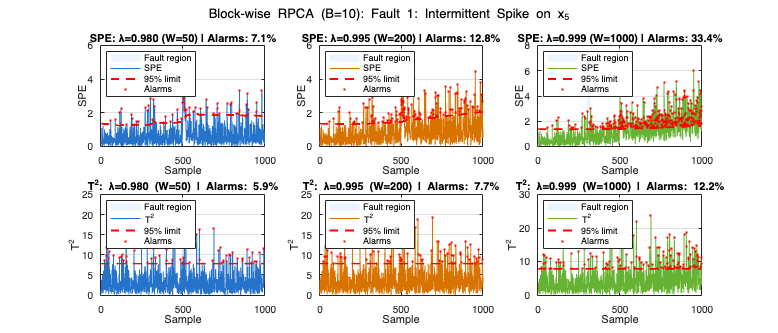


%% 6b: Fault 1: Spike on x5

di = 2;

figure('Position', [100 100 1400 600])

for li = 1:3
    SPE_cur    = SPE_bw{di, li};
    T2_cur     = T2_bw{di, li};
    SPElim_cur = SPElim_bw{di, li};
    T2lim_cur  = T2lim_bw{di, li};

    subplot(2,3,li); hold on
    fill([300 320 320 300], [0 0 max(SPE_cur)*1.2 max(SPE_cur)*1.2], ...
         fault_colors(1,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(SPE_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(SPElim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(SPE_cur > SPElim_cur);
    plot(alarm_idx, SPE_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE')
    title(sprintf('SPE: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(SPE_cur > SPElim_cur)))
    legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    subplot(2,3,li+3); hold on
    fill([300 320 320 300], [0 0 max(T2_cur)*1.2 max(T2_cur)*1.2], ...
         fault_colors(1,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(T2_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(T2lim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(T2_cur > T2lim_cur);
    plot(alarm_idx, T2_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2')
    title(sprintf('T^2: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(T2_cur > T2lim_cur)))
    legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
    grid on; box on
end

sgtitle('Block-wise RPCA (B=10): Fault 1: Intermittent Spike on x_5', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_6b_bw_fault1.png'), 'Resolution', 300)

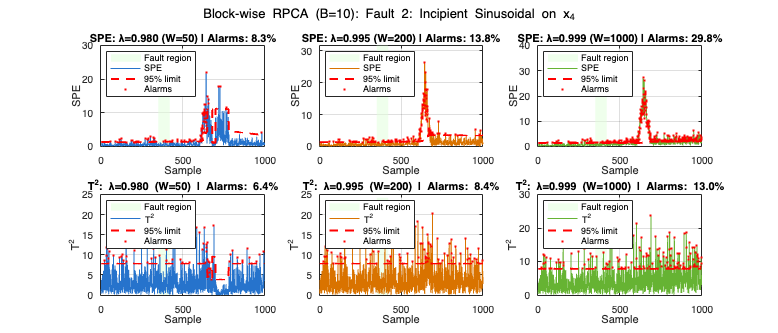

drawnow

%% 6c: Fault 2: Incipient sinusoidal on x4

di = 3;

figure('Position', [100 100 1400 600])

for li = 1:3
    SPE_cur    = SPE_bw{di, li};
    T2_cur     = T2_bw{di, li};
    SPElim_cur = SPElim_bw{di, li};
    T2lim_cur  = T2lim_bw{di, li};

    subplot(2,3,li); hold on
    fill([350 420 420 350], [0 0 max(SPE_cur)*1.2 max(SPE_cur)*1.2], ...
         fault_colors(2,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(SPE_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(SPElim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(SPE_cur > SPElim_cur);
    plot(alarm_idx, SPE_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE')
    title(sprintf('SPE: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(SPE_cur > SPElim_cur)))
    legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    subplot(2,3,li+3); hold on
    fill([350 420 420 350], [0 0 max(T2_cur)*1.2 max(T2_cur)*1.2], ...
         fault_colors(2,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(T2_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(T2lim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(T2_cur > T2lim_cur);
    plot(alarm_idx, T2_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2')
    title(sprintf('T^2: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(T2_cur > T2lim_cur)))
    legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
    grid on; box on
end

sgtitle('Block-wise RPCA (B=10): Fault 2: Incipient Sinusoidal on x_4', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_6c_bw_fault2.png'), 'Resolution', 300)

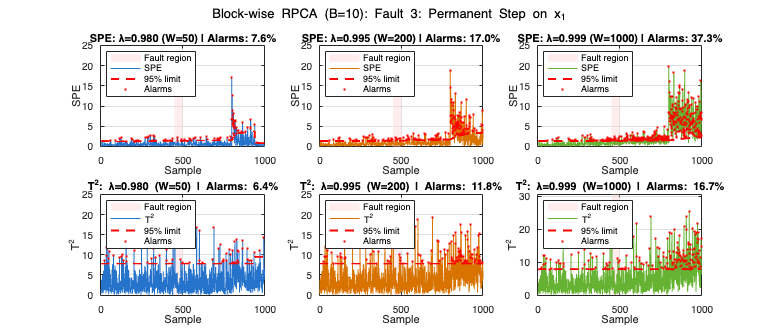


%% 6d: Fault 3: Permanent step on x1

di = 4;

figure('Position', [100 100 1400 600])

for li = 1:3
    SPE_cur    = SPE_bw{di, li};
    T2_cur     = T2_bw{di, li};
    SPElim_cur = SPElim_bw{di, li};
    T2lim_cur  = T2lim_bw{di, li};

    subplot(2,3,li); hold on
    fill([450 500 500 450], [0 0 max(SPE_cur)*1.2 max(SPE_cur)*1.2], ...
         fault_colors(3,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(SPE_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(SPElim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(SPE_cur > SPElim_cur);
    plot(alarm_idx, SPE_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE')
    title(sprintf('SPE: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(SPE_cur > SPElim_cur)))
    legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    subplot(2,3,li+3); hold on
    fill([450 500 500 450], [0 0 max(T2_cur)*1.2 max(T2_cur)*1.2], ...
         fault_colors(3,:), 'EdgeColor','none','FaceAlpha',0.5)
    plot(T2_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(T2lim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(T2_cur > T2lim_cur);
    plot(alarm_idx, T2_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2')
    title(sprintf('T^2: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(T2_cur > T2lim_cur)))
    legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
    grid on; box on
end

sgtitle('Block-wise RPCA (B=10): Fault 3: Permanent Step on x_1', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_6d_bw_fault3.png'), 'Resolution', 300)

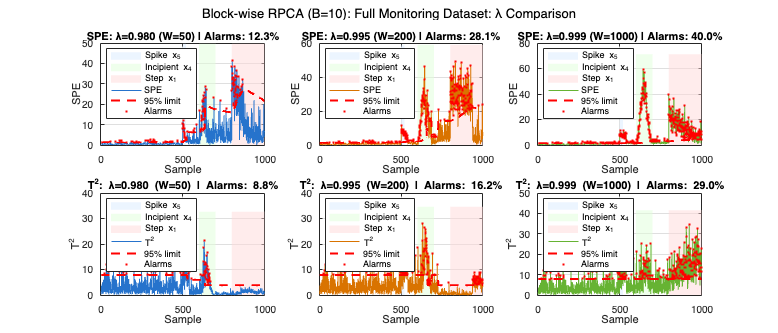

drawnow

%% 6e: Full Monitoring Dataset

di = 5;

figure('Position', [100 100 1400 600])

for li = 1:3
    SPE_cur    = SPE_bw{di, li};
    T2_cur     = T2_bw{di, li};
    SPElim_cur = SPElim_bw{di, li};
    T2lim_cur  = T2lim_bw{di, li};

    subplot(2,3,li); hold on
    for f = 1:3
        fill([fault_regions(f,1) fault_regions(f,2) ...
              fault_regions(f,2) fault_regions(f,1)], ...
             [0 0 max(SPE_cur)*1.2 max(SPE_cur)*1.2], ...
             fault_colors(f,:), 'EdgeColor','none','FaceAlpha',0.5)
    end
    plot(SPE_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(SPElim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(SPE_cur > SPElim_cur);
    plot(alarm_idx, SPE_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE')
    title(sprintf('SPE: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(SPE_cur > SPElim_cur)))
    legend('Spike x_5','Incipient x_4','Step x_1', ...
           'SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    subplot(2,3,li+3); hold on
    for f = 1:3
        fill([fault_regions(f,1) fault_regions(f,2) ...
              fault_regions(f,2) fault_regions(f,1)], ...
             [0 0 max(T2_cur)*1.2 max(T2_cur)*1.2], ...
             fault_colors(f,:), 'EdgeColor','none','FaceAlpha',0.5)
    end
    plot(T2_cur, 'Color', colors_lam{li}, 'LineWidth', 0.9)
    plot(T2lim_cur, 'r--', 'LineWidth', 2)
    alarm_idx = find(T2_cur > T2lim_cur);
    plot(alarm_idx, T2_cur(alarm_idx), 'r.', 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2')
    title(sprintf('T^2: %s | Alarms: %.1f%%', lam_labels{li}, ...
          100*mean(T2_cur > T2lim_cur)))
    legend('Spike x_5','Incipient x_4','Step x_1', ...
           'T^2','95% limit','Alarms','Location','northwest')
    grid on; box on
end

sgtitle('Block-wise RPCA (B=10): Full Monitoring Dataset: λ Comparison', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_6e_bw_full.png'), 'Resolution', 300)

## 7. VRE: Block-wise Adaptive q Evolution

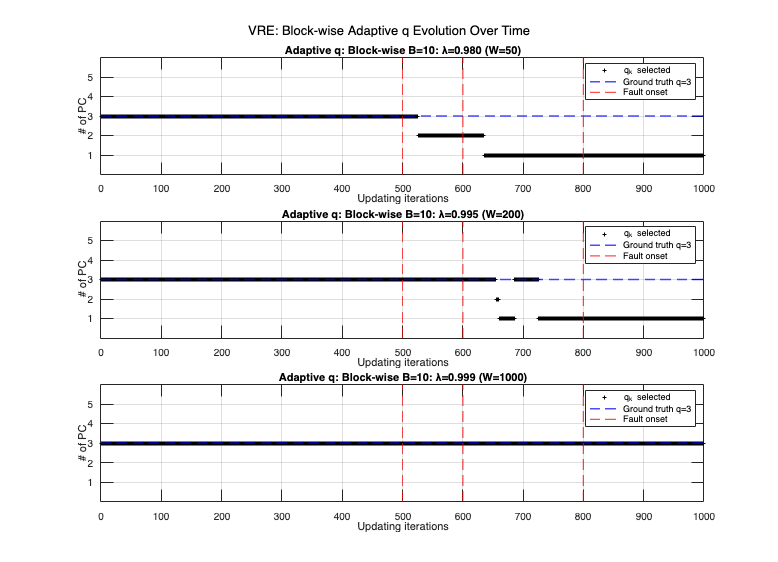


%% 7. VRE: Block-wise Adaptive q Evolution

di = 5;   % Z_mon full dataset

figure('Position', [100 100 900 650])

for li = 1:3
    subplot(3,1,li); hold on
    plot(1:N2, q_bw{di,li}, 'k+', 'MarkerSize', 4, 'LineWidth', 0.8)
    yline(3, 'b--', 'LineWidth', 1.5)
    xline(fault_regions(1,1), 'r--', 'LineWidth', 1.2)
    xline(fault_regions(2,1), 'r--', 'LineWidth', 1.2)
    xline(fault_regions(3,1), 'r--', 'LineWidth', 1.2)
    ylim([0 q_max+1])
    yticks(1:q_max)
    xlabel('Updating iterations'); ylabel('# of PC')
    title(sprintf('Adaptive q: Block-wise B=10: %s', lam_labels{li}))
    legend('q_k selected','Ground truth q=3','Fault onset','Location','northeast')
    grid on; box on
end

sgtitle('VRE: Block-wise Adaptive q Evolution Over Time', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_7_bw_q_evolution.png'), 'Resolution', 300)

## 8. Sample-wise vs Block-wise Comparison (λ=0.995)

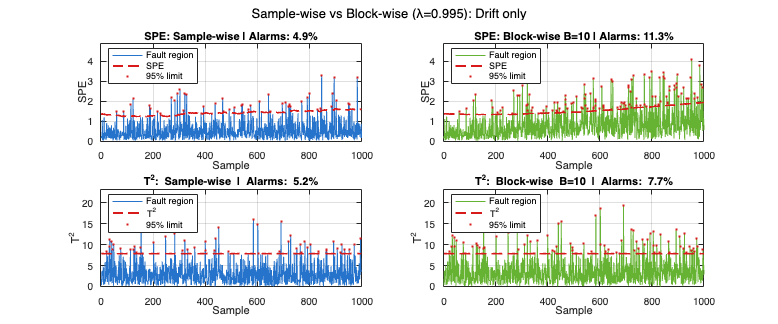

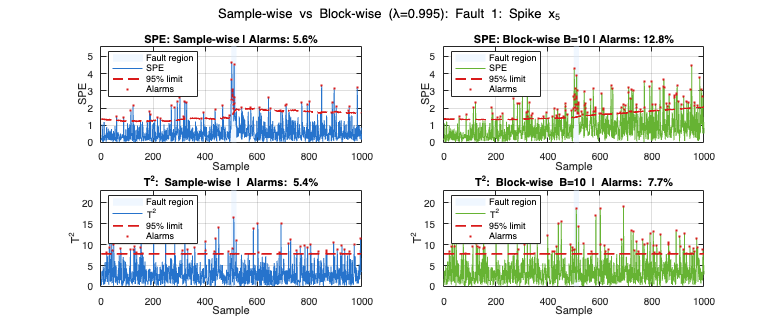

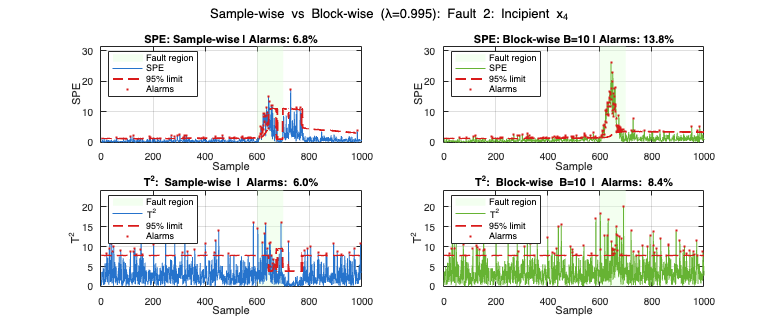

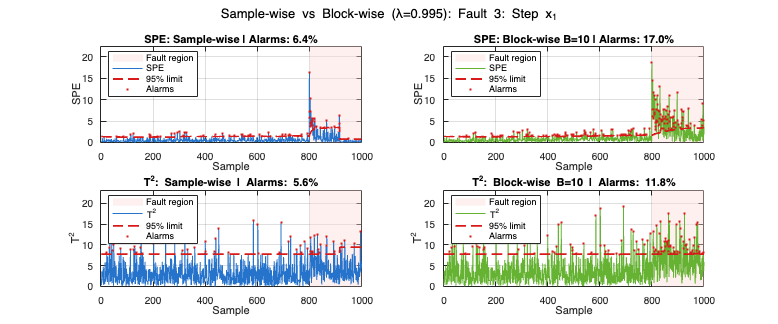

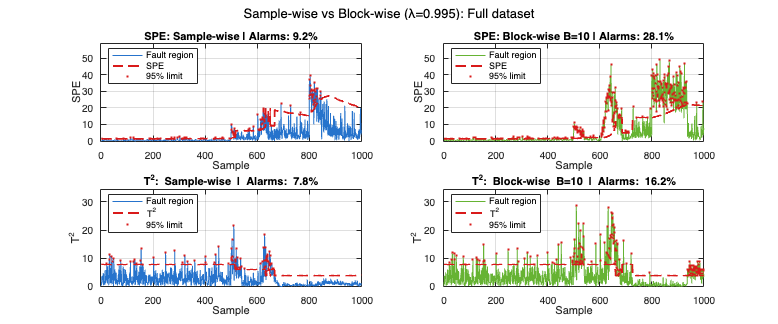

%% 8. Sample-wise vs Block-wise Comparison (λ=0.995)

li  = 2;   % λ=0.995

color_sw  = [0.15 0.45 0.80];   % blue : sample-wise
color_bw  = [0.40 0.70 0.20];   % green: block-wise
color_lim = [0.85 0.10 0.10];   % red  : limits

datasets_names_short = {'Drift only', 'Fault 1: Spike x_5', ...
                        'Fault 2: Incipient x_4', 'Fault 3: Step x_1', ...
                        'Full dataset'};
fault_fills = {[], [500 520], [600 700], [800 1000], []};
fault_idx   = [0, 1, 2, 3, 0];   % 0 = no fault fill

for di = 1:n_ds

    SPE_sw_cur    = SPE_sw{di, li};
    T2_sw_cur     = T2_sw{di, li};
    SPElim_sw_cur = SPElim_sw{di, li};
    T2lim_sw_cur  = T2lim_sw{di, li};

    SPE_bw_cur    = SPE_bw{di, li};
    T2_bw_cur     = T2_bw{di, li};
    SPElim_bw_cur = SPElim_bw{di, li};
    T2lim_bw_cur  = T2lim_bw{di, li};

    y_spe = max([SPE_sw_cur; SPE_bw_cur]) * 1.2;
    y_t2  = max([T2_sw_cur;  T2_bw_cur])  * 1.2;

    figure('Position', [100 100 1200 500])

    %% SPE: Sample-wise
    subplot(2,2,1); hold on
    if fault_idx(di) > 0
        fr = fault_fills{di};
        fill([fr(1) fr(2) fr(2) fr(1)], [0 0 y_spe y_spe], ...
             fault_colors(fault_idx(di),:), 'EdgeColor','none','FaceAlpha',0.4)
    end
    plot(SPE_sw_cur, 'Color', color_sw, 'LineWidth', 0.9)
    plot(SPElim_sw_cur, '--', 'Color', color_lim, 'LineWidth', 1.8)
    alarm_idx_sw = find(SPE_sw_cur > SPElim_sw_cur);
    plot(alarm_idx_sw, SPE_sw_cur(alarm_idx_sw), '.', 'Color', color_lim, 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE'); ylim([0 y_spe])
    title(sprintf('SPE: Sample-wise | Alarms: %.1f%%', ...
          100*mean(SPE_sw_cur > SPElim_sw_cur)))
    legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    %% SPE: Block-wise
    subplot(2,2,2); hold on
    if fault_idx(di) > 0
        fr = fault_fills{di};
        fill([fr(1) fr(2) fr(2) fr(1)], [0 0 y_spe y_spe], ...
             fault_colors(fault_idx(di),:), 'EdgeColor','none','FaceAlpha',0.4)
    end
    plot(SPE_bw_cur, 'Color', color_bw, 'LineWidth', 0.9)
    plot(SPElim_bw_cur, '--', 'Color', color_lim, 'LineWidth', 1.8)
    alarm_idx_bw = find(SPE_bw_cur > SPElim_bw_cur);
    plot(alarm_idx_bw, SPE_bw_cur(alarm_idx_bw), '.', 'Color', color_lim, 'MarkerSize', 6)
    xlabel('Sample'); ylabel('SPE'); ylim([0 y_spe])
    title(sprintf('SPE: Block-wise B=10 | Alarms: %.1f%%', ...
          100*mean(SPE_bw_cur > SPElim_bw_cur)))
    legend('Fault region','SPE','95% limit','Alarms','Location','northwest')
    grid on; box on

    %% T²: Sample-wise
    subplot(2,2,3); hold on
    if fault_idx(di) > 0
        fr = fault_fills{di};
        fill([fr(1) fr(2) fr(2) fr(1)], [0 0 y_t2 y_t2], ...
             fault_colors(fault_idx(di),:), 'EdgeColor','none','FaceAlpha',0.4)
    end
    plot(T2_sw_cur, 'Color', color_sw, 'LineWidth', 0.9)
    plot(T2lim_sw_cur, '--', 'Color', color_lim, 'LineWidth', 1.8)
    alarm_idx_sw = find(T2_sw_cur > T2lim_sw_cur);
    plot(alarm_idx_sw, T2_sw_cur(alarm_idx_sw), '.', 'Color', color_lim, 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2'); ylim([0 y_t2])
    title(sprintf('T^2: Sample-wise | Alarms: %.1f%%', ...
          100*mean(T2_sw_cur > T2lim_sw_cur)))
    legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
    grid on; box on

    %% T²: Block-wise
    subplot(2,2,4); hold on
    if fault_idx(di) > 0
        fr = fault_fills{di};
        fill([fr(1) fr(2) fr(2) fr(1)], [0 0 y_t2 y_t2], ...
             fault_colors(fault_idx(di),:), 'EdgeColor','none','FaceAlpha',0.4)
    end
    plot(T2_bw_cur, 'Color', color_bw, 'LineWidth', 0.9)
    plot(T2lim_bw_cur, '--', 'Color', color_lim, 'LineWidth', 1.8)
    alarm_idx_bw = find(T2_bw_cur > T2lim_bw_cur);
    plot(alarm_idx_bw, T2_bw_cur(alarm_idx_bw), '.', 'Color', color_lim, 'MarkerSize', 6)
    xlabel('Sample'); ylabel('T^2'); ylim([0 y_t2])
    title(sprintf('T^2: Block-wise B=10 | Alarms: %.1f%%', ...
          100*mean(T2_bw_cur > T2lim_bw_cur)))
    legend('Fault region','T^2','95% limit','Alarms','Location','northwest')
    grid on; box on

    sgtitle(sprintf('Sample-wise vs Block-wise (λ=0.995): %s', ...
            datasets_names_short{di}), 'FontSize', 13)
   exportgraphics(gcf, fullfile(plots_dir, sprintf('rpca_8_%d_sw_vs_bw.png', di)), 'Resolution', 300)

end

## 8b. Contribution Plots — Sample-wise vs Block-wise (λ=0.995)

#### At a representative sample inside each fault window, SPE is decomposed per sensor:

### 
$$c_i = \frac{e_i^2}{\text{SPE}} \times 100, \qquad e_i = \tilde{x}_i - \hat{x}_i$$


#### Sample-wise and block-wise use their respective adaptive loading matrix P_k� at that specific sample, recomputed by fast-forwarding the recursive loop to k_c.�

**Limitation:** strong drift on x_2� and t_1� can mask fault contribution for Faults 2 and 3: the absolute residual is dominated by drift rather than the injected fault.

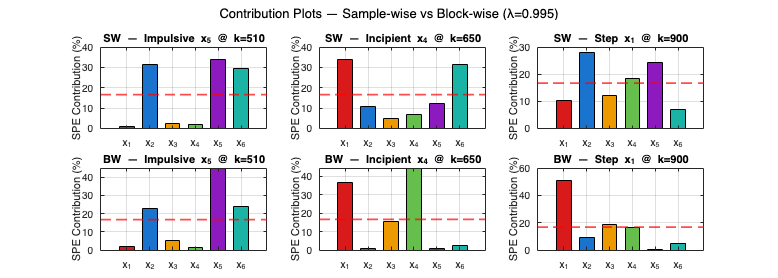

%% 8b. Contribution Plots — Sample-wise vs Block-wise (λ=0.995)

li = 2;   % λ=0.995

k_samples = [510, 660, 850];  % picco incipient ~k=650, step ben dentrofault_di    = [2, 3, 4];
fault_titles = {'Impulsive x_5 @ k=510', ...
                'Incipient x_4 @ k=650', ...
                'Step x_1 @ k=900'};

figure('Position', [100 100 1400 500])

for fi = 1:3

    di  = fault_di(fi);
    k_c = k_samples(fi);
    lam = lambdas(li);

    %% Sample-wise contribution at k_c
    Z_cur = datasets{di};
    X_cur = Z_cur .* sigma + mu;

    mu_r = mu'; R_r = corr(Z);
    for k = 1:k_c
        x_raw   = X_cur(k,:)';
        mu_old  = mu_r;
        mu_r    = lam * mu_r + (1-lam) * x_raw;
        delta_b = mu_r - mu_old;
        x_tilde = (x_raw - mu_r) ./ sigma';
        v1      = delta_b ./ sigma';
        v2      = sqrt(1-lam) * x_tilde;
        R_r     = lam * R_r + v1*v1' + v2*v2';
    end

    [Phi, alpha_l, beta_l, m1] = lanczos_tridiag(R_r, rho, q_max);
    n_eig = min(m1, q_max);

    lambda_eig = zeros(n_eig,1);
    for i = 1:n_eig
        lambda_eig(i) = bisection_eig(alpha_l, beta_l, i, eps_bis);
    end
    C_lk = zeros(m1, n_eig);
    for i = 1:n_eig
        C_lk(:,i) = inverse_iteration(alpha_l, beta_l, lambda_eig(i), delta_inv);
    end
    P_full = Phi * C_lk;

    VRE_test = zeros(n_eig,1);
    for q_test = 1:n_eig
        P_t = P_full(:,1:q_test); C_t = P_t*P_t';
        u_var = zeros(m,1);
        for j = 1:m
            num = R_r(j,j) - 2*C_t(:,j)'*R_r(:,j) + C_t(:,j)'*R_r*C_t(:,j);
            u_var(j) = max(num/(1-C_t(j,j))^2, 1e-10);
        end
        VRE_test(q_test) = sum(u_var ./ diag(R_r));
    end
    [~, q_opt] = min(VRE_test);
    P_lk = P_full(:,1:q_opt);

    x_raw_c   = X_cur(k_c,:)';
    x_tilde_c = (x_raw_c - mu_r) ./ sigma';
    scores_c   = P_lk' * x_tilde_c;
    residual_c = x_tilde_c - P_lk * scores_c;
    contrib_sw  = 100 * residual_c.^2 / sum(residual_c.^2);

    %% Block-wise contribution at k_c
    mu_r = mu'; R_r = corr(Z);
    buffer = zeros(B, m); n_buf = 0;

    % Initialize
    [Phi, alpha_l, beta_l, m1] = lanczos_tridiag(R_r, rho, q_max);
    n_eig = min(m1, q_max);
    lambda_eig = zeros(n_eig,1);
    for i = 1:n_eig; lambda_eig(i) = bisection_eig(alpha_l, beta_l, i, eps_bis); end
    C_lk = zeros(m1,n_eig);
    for i = 1:n_eig; C_lk(:,i) = inverse_iteration(alpha_l, beta_l, lambda_eig(i), delta_inv); end
    P_full = Phi * C_lk;
    VRE_init = zeros(n_eig,1);
    for q_test = 1:n_eig
        P_t = P_full(:,1:q_test); C_t = P_t*P_t';
        u_var = zeros(m,1);
        for j = 1:m
            num = R_r(j,j) - 2*C_t(:,j)'*R_r(:,j) + C_t(:,j)'*R_r*C_t(:,j);
            u_var(j) = max(num/(1-C_t(j,j))^2, 1e-10);
        end
        VRE_init(q_test) = sum(u_var ./ diag(R_r));
    end
    [~, q_cur] = min(VRE_init);
    P_cur = P_full(:,1:q_cur);

    for k = 1:k_c
        x_raw   = X_cur(k,:)';
        x_tilde = (x_raw - mu_r) ./ sigma';
        n_buf   = n_buf + 1;
        buffer(n_buf,:) = x_raw';

        if n_buf == B
            x_block_mean = mean(buffer,1)';
            mu_old  = mu_r;
            mu_r    = lam * mu_r + (1-lam) * x_block_mean;
            delta_b = mu_r - mu_old;
            x_norm_block = (buffer - mu_r') ./ sigma;
            v1  = delta_b ./ sigma';
            R_r = lam * R_r + v1*v1' + (1-lam)*(x_norm_block'*x_norm_block)/B;
            R_r = (R_r + R_r')/2;

            [Phi, alpha_l, beta_l, m1] = lanczos_tridiag(R_r, rho, q_max);
            n_eig = min(m1, q_max);
            lambda_eig = zeros(n_eig,1);
            for i = 1:n_eig; lambda_eig(i) = bisection_eig(alpha_l, beta_l, i, eps_bis); end
            C_lk = zeros(m1,n_eig);
            for i = 1:n_eig; C_lk(:,i) = inverse_iteration(alpha_l, beta_l, lambda_eig(i), delta_inv); end
            P_full = Phi * C_lk;
            VRE_test = zeros(n_eig,1);
            for q_test = 1:n_eig
                P_t = P_full(:,1:q_test); C_t = P_t*P_t';
                u_var = zeros(m,1);
                for j = 1:m
                    num = R_r(j,j) - 2*C_t(:,j)'*R_r(:,j) + C_t(:,j)'*R_r*C_t(:,j);
                    u_var(j) = max(num/(1-C_t(j,j))^2, 1e-10);
                end
                VRE_test(q_test) = sum(u_var ./ diag(R_r));
            end
            [~, q_cur] = min(VRE_test);
            P_cur = P_full(:,1:q_cur);
            buffer = zeros(B,m); n_buf = 0;
        end
    end

    x_raw_c   = X_cur(k_c,:)';
    x_tilde_c = (x_raw_c - mu_r) ./ sigma';
    scores_c   = P_cur' * x_tilde_c;
    residual_c = x_tilde_c - P_cur * scores_c;
    contrib_bw  = 100 * residual_c.^2 / sum(residual_c.^2);

    %% Plot side by side
    subplot(2,3,fi)
    b_h = bar(1:m, contrib_sw, 0.65);
    b_h.FaceColor = 'flat'; b_h.CData = arrow_cols; b_h.EdgeColor = 'k';
    hold on
    yline(100/m, 'r--', 'LineWidth', 1.8)
    xticks(1:m); xticklabels(var_names)
    ylabel('SPE Contribution (%)')
    title(sprintf('SW — %s', fault_titles{fi}))
    grid on; box on

    subplot(2,3,fi+3)
    b_h = bar(1:m, contrib_bw, 0.65);
    b_h.FaceColor = 'flat'; b_h.CData = arrow_cols; b_h.EdgeColor = 'k';
    hold on
    yline(100/m, 'r--', 'LineWidth', 1.8)
    xticks(1:m); xticklabels(var_names)
    ylabel('SPE Contribution (%)')
    title(sprintf('BW — %s', fault_titles{fi}))
    grid on; box on

end

sgtitle('Contribution Plots — Sample-wise vs Block-wise (λ=0.995)', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_8b_contributions.png'), 'Resolution', 300)

- (BW) x_5� correctly isolated in Fault 1: impulsive fault is large enough to dominate residual

- Faults 2 and 3: drift masks true fault source: contribution plot not conclusive

- Limitation of absolute SPE contribution in presence of strong drift

## 9. Performance Metrics: Batch PCA vs RPCA Sample-wise vs Block-wise

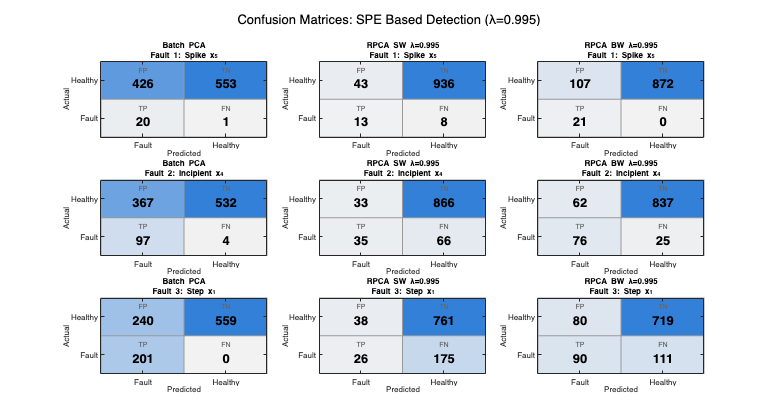

%% 9. Performance Metrics: Batch PCA vs RPCA Sample-wise vs Block-wise


% Ground truth per fault
GT_f1 = zeros(N2,1); GT_f1(500:520)  = 1;
GT_f2 = zeros(N2,1); GT_f2(600:700)  = 1;
GT_f3 = zeros(N2,1); GT_f3(800:1000) = 1;
GT    = {GT_f1, GT_f2, GT_f3};

fault_names  = {'Fault 1: Spike x_5', 'Fault 2: Incipient x_4', 'Fault 3: Step x_1'};
method_names = {'Batch PCA', 'RPCA SW λ=0.995', 'RPCA BW λ=0.995'};
li           = 2;   % λ=0.995

% Batch PCA SPE on single-fault datasets
Z_faults      = {Z_mon_f1, Z_mon_f2, Z_mon_f3};
scores_batch  = cellfun(@(Z) Z*Vq, Z_faults, 'UniformOutput', false);
SPE_batch     = cellfun(@(Z,s) sum((Z - s*Vq').^2, 2), Z_faults, scores_batch, ...
                'UniformOutput', false);

% RPCA SW SPE on single-fault datasets (di=2,3,4)
SPE_rpca_sw = {SPE_sw{2,li}, SPE_sw{3,li}, SPE_sw{4,li}};
SPElim_rpca_sw = {SPElim_sw{2,li}, SPElim_sw{3,li}, SPElim_sw{4,li}};

% RPCA BW SPE on single-fault datasets
SPE_rpca_bw = {SPE_bw{2,li}, SPE_bw{3,li}, SPE_bw{4,li}};
SPElim_rpca_bw = {SPElim_bw{2,li}, SPElim_bw{3,li}, SPElim_bw{4,li}};

% Storage
Prec  = zeros(3,3);   % (method, fault)
Rec   = zeros(3,3);
F1    = zeros(3,3);
CM    = zeros(2,2,3,3);   % confusion matrix (2x2, method, fault)

for fi = 1:3
    gt = GT{fi};

    % --- Batch PCA ---
    pred = SPE_batch{fi} > SPE_lim_batch;
    TP = sum(pred(gt==1)); FP = sum(pred(gt==0));
    FN = sum(~pred(gt==1)); TN = sum(~pred(gt==0));
    CM(:,:,1,fi) = [TP FN; FP TN];
    Prec(1,fi) = TP / max(TP+FP, 1);
    Rec(1,fi)  = TP / max(TP+FN, 1);
    F1(1,fi)   = 2*Prec(1,fi)*Rec(1,fi) / max(Prec(1,fi)+Rec(1,fi), 1e-10);

    % --- RPCA Sample-wise ---
    pred = SPE_rpca_sw{fi} > SPElim_rpca_sw{fi};
    TP = sum(pred(gt==1)); FP = sum(pred(gt==0));
    FN = sum(~pred(gt==1)); TN = sum(~pred(gt==0));
    CM(:,:,2,fi) = [TP FN; FP TN];
    Prec(2,fi) = TP / max(TP+FP, 1);
    Rec(2,fi)  = TP / max(TP+FN, 1);
    F1(2,fi)   = 2*Prec(2,fi)*Rec(2,fi) / max(Prec(2,fi)+Rec(2,fi), 1e-10);

    % --- RPCA Block-wise ---
    pred = SPE_rpca_bw{fi} > SPElim_rpca_bw{fi};
    TP = sum(pred(gt==1)); FP = sum(pred(gt==0));
    FN = sum(~pred(gt==1)); TN = sum(~pred(gt==0));
    CM(:,:,3,fi) = [TP FN; FP TN];
    Prec(3,fi) = TP / max(TP+FP, 1);
    Rec(3,fi)  = TP / max(TP+FN, 1);
    F1(3,fi)   = 2*Prec(3,fi)*Rec(3,fi) / max(Prec(3,fi)+Rec(3,fi), 1e-10);
end

%% 9a: Confusion Matrices

figure('Position', [100 100 1400 750])

cm_labels    = {'Fault', 'Healthy'};
color_high   = [0.20 0.50 0.85];   % blue: high value
color_low    = [0.95 0.95 0.95];   % light gray: low value

plot_idx = 1;

for fi = 1:3
    for mi = 1:3

        subplot(3,3,plot_idx)
        cm = CM(:,:,mi,fi);

        % Background colors per cell
        for r = 1:2
            for c = 1:2
                val_norm = cm(r,c) / max(cm(:));
                fc = color_low + val_norm * (color_high - color_low);
                fill([c-0.5 c+0.5 c+0.5 c-0.5], ...
                     [r-0.5 r-0.5 r+0.5 r+0.5], fc, ...
                     'EdgeColor', [0.6 0.6 0.6], 'LineWidth', 1.2)
                hold on
                % Cell label (TP/FN/FP/TN)
                cell_labels = {'TP','FN';'FP','TN'};
                text(c, r+0.28, cell_labels{r,c}, ...
                     'HorizontalAlignment','center', ...
                     'FontSize', 7, 'Color', [0.4 0.4 0.4])
                % Value
                text(c, r-0.08, num2str(cm(r,c)), ...
                     'HorizontalAlignment','center', ...
                     'FontSize', 13, 'FontWeight','bold', ...
                     'Color', 'k')
            end
        end

        % Axes
        set(gca, 'XTick', 1:2, 'XTickLabel', cm_labels, ...
                 'YTick', 1:2, 'YTickLabel', cm_labels, ...
                 'YDir', 'normal', 'FontSize', 8)
        xlim([0.5 2.5]); ylim([0.5 2.5])
        xlabel('Predicted', 'FontSize', 8)
        ylabel('Actual', 'FontSize', 8)
        title(sprintf('\\bf%s\\rm\n%s', method_names{mi}, fault_names{fi}), ...
              'FontSize', 7.5, 'Interpreter', 'tex')
        box on

        plot_idx = plot_idx + 1;
    end
end

sgtitle('Confusion Matrices: SPE Based Detection (λ=0.995)', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_9a_confusion_matrices.png'), 'Resolution', 300)


%% 9b: F1 Summary Table

T_f1 = table(method_names', ...
    round(F1(:,1),3), round(Prec(:,1),3), round(Rec(:,1),3), ...
    round(F1(:,2),3), round(Prec(:,2),3), round(Rec(:,2),3), ...
    round(F1(:,3),3), round(Prec(:,3),3), round(Rec(:,3),3), ...
    'VariableNames', {'Method', ...
    'F1_spike','Prec_spike','Rec_spike', ...
    'F1_incip','Prec_incip','Rec_incip', ...
    'F1_step', 'Prec_step', 'Rec_step'});

disp('--- F1 Metrics Summary (SPE, λ=0.995) ---')

--- F1 Metrics Summary (SPE, λ=0.995) ---


disp(T_f1)

          Method           F1_spike    Prec_spike    Rec_spike    F1_incip    Prec_incip    Rec_incip    F1_step    Prec_step    Rec_step
    ___________________    ________    __________    _________    ________    __________    _________    _______    _________    ________

    {'Batch PCA'      }     0.086        0.045         0.952       0.343        0.209          0.96       0.626       0.456           1  
    {'RPCA SW λ=0.995'}     0.338        0.232         0.619       0.414        0.515         0.347       0.196       0.406       0.129  
    {'RPCA BW λ=0.995'}     0.282        0.164             1       0.636        0.551         0.752       0

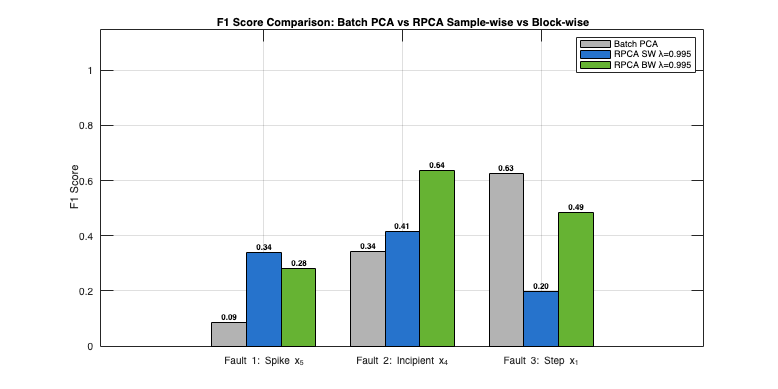


%% 9c: F1 Bar Chart

colors_method = [0.7 0.7 0.7;        % Batch PCA: gray
                 0.15 0.45 0.80;      % RPCA SW  : blue
                 0.40 0.70 0.20];     % RPCA BW  : green

figure('Position', [100 100 900 450])

x = 1:3;
bar_width = 0.25;
offsets   = [-bar_width, 0, bar_width];

hold on
for mi = 1:3
    bar(x + offsets(mi), F1(mi,:), bar_width, ...
        'FaceColor', colors_method(mi,:), 'EdgeColor', 'k', 'LineWidth', 0.8)
end

% Value labels on bars
for mi = 1:3
    for fi = 1:3
        text(fi + offsets(mi), F1(mi,fi) + 0.02, ...
             sprintf('%.2f', F1(mi,fi)), ...
             'HorizontalAlignment', 'center', 'FontSize', 8, 'FontWeight', 'bold')
    end
end

xticks(1:3); xticklabels(fault_names)
ylabel('F1 Score')
ylim([0 1.15])
title('F1 Score Comparison: Batch PCA vs RPCA Sample-wise vs Block-wise')
legend(method_names, 'Location', 'northeast')
grid on; box on

exportgraphics(gcf, fullfile(plots_dir, 'rpca_9b_f1_comparison.png'), 'Resolution', 300)

%% 9d: FAR vs DR Table (the correct metric for time-varying processes)

% FAR = false alarm rate on healthy drift samples
% DR  = detection rate on fault samples

FAR_drift = zeros(3,1);   % on drift-only dataset
DR        = zeros(3,3);   % (method, fault)

% Batch PCA on drift-only
SPE_batch_drift = sum((Z_mon_drift - (Z_mon_drift*Vq)*Vq').^2, 2);
FAR_drift(1)    = 100*mean(SPE_batch_drift > SPE_lim_batch);

% RPCA SW on drift-only
FAR_drift(2) = 100*mean(SPE_sw{1,li} > SPElim_sw{1,li});

% RPCA BW on drift-only
FAR_drift(3) = 100*mean(SPE_bw{1,li} > SPElim_bw{1,li});

% DR per fault
for fi = 1:3
    gt = GT{fi};

    % Batch PCA
    pred = SPE_batch{fi} > SPE_lim_batch;
    DR(1,fi) = 100*mean(pred(gt==1));

    % RPCA SW
    pred = SPE_rpca_sw{fi} > SPElim_rpca_sw{fi};
    DR(2,fi) = 100*mean(pred(gt==1));

    % RPCA BW
    pred = SPE_rpca_bw{fi} > SPElim_rpca_bw{fi};
    DR(3,fi) = 100*mean(pred(gt==1));
end

% Table
T_far_dr = table(method_names', ...
    round(FAR_drift,1), ...
    round(DR(:,1),1), round(DR(:,2),1), round(DR(:,3),1), ...
    'VariableNames', {'Method','FAR_drift_pct', ...
    'DR_spike_pct','DR_incipient_pct','DR_step_pct'});

disp('--- FAR on Drift vs DR on Fault (SPE, λ=0.995) ---')

--- FAR on Drift vs DR on Fault (SPE, λ=0.995) ---


disp(T_far_dr)

          Method           FAR_drift_pct    DR_spike_pct    DR_incipient_pct    DR_step_pct
    ___________________    _____________    ____________    ________________    ___________

    {'Batch PCA'      }        42.9             95.2                96              100    
    {'RPCA SW λ=0.995'}         4.9             61.9              34.7             12.9    
    {'RPCA BW λ=0.995'}        11.3              100              75.2             44.8    



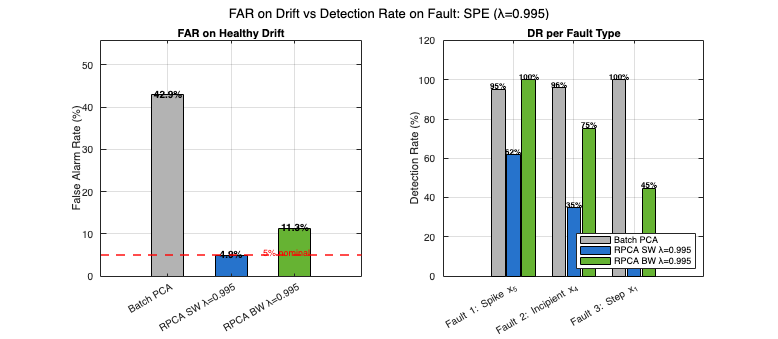


%% 9e: FAR vs DR Plot

figure('Position', [100 100 1100 480])

subplot(1,2,1)
b = bar(1:3, FAR_drift, 0.5);
b.FaceColor = 'flat';
b.CData = colors_method;
b.EdgeColor = 'k'; b.LineWidth = 0.8;
hold on
yline(5, 'r--', 'LineWidth', 2)
for mi = 1:3
    text(mi, FAR_drift(mi) + 0.3, sprintf('%.1f%%', FAR_drift(mi)), ...
         'HorizontalAlignment','center','FontSize',10,'FontWeight','bold')
end
xticks(1:3); xticklabels(method_names)
ylabel('False Alarm Rate (%)')
title('FAR on Healthy Drift')
text(2.5, 5.4, '5% nominal', 'Color','r','FontSize',9)
ylim([0 max(FAR_drift)*1.3])
grid on; box on

subplot(1,2,2); hold on
x       = 1:3;
offsets = [-0.25, 0, 0.25];

for mi = 1:3
    bar(x + offsets(mi), DR(mi,:), 0.22, ...
        'FaceColor', colors_method(mi,:), 'EdgeColor','k','LineWidth',0.8)
end
for mi = 1:3
    for fi = 1:3
        text(fi + offsets(mi), DR(mi,fi) + 1.5, sprintf('%.0f%%', DR(mi,fi)), ...
             'HorizontalAlignment','center','FontSize',8,'FontWeight','bold')
    end
end
xticks(1:3); xticklabels(fault_names)
ylabel('Detection Rate (%)')
title('DR per Fault Type')
legend(method_names,'Location','southeast')
ylim([0 120])
grid on; box on

sgtitle('FAR on Drift vs Detection Rate on Fault: SPE (λ=0.995)', 'FontSize', 13)
exportgraphics(gcf, fullfile(plots_dir, 'rpca_9d_far_dr.png'), 'Resolution', 300)

## 10 Computational Comparison Sample-Wise vs Block-Wise

tic
% loop sample-wise
t_sw = toc;

tic  
% loop block-wise
t_bw = toc;

fprintf('SW: %.6fs | BW: %.6fs | Speedup: %.1fx\n', t_sw, t_bw, t_sw/t_bw)

SW: 0.001461s | BW: 0.000366s | Speedup: 4.0x


% Count of Lanczos Calls
n_lanczos_sw = N2;           % one per sample
n_lanczos_bw = floor(N2/B);  % one per block

fprintf('SW: %d Lanczos calls\n', n_lanczos_sw)

SW: 1000 Lanczos calls


fprintf('BW: %d Lanczos calls | Speedup: %.1fx\n', n_lanczos_bw, N2/n_lanczos_bw)

BW: 200 Lanczos calls | Speedup: 5.0x
